load 'C:\class\coursefiles\mlbe\exercises\hurricaneData.mat'

plot(Dates,Windspeed,'.')

[Windspeed,idx] = sort(Windspeed,'descend');
top10 = Windspeed(1:10)

top10 =    184
   178
   173
   173
   173
   173
   173
   173
   167
   167


winDate = Dates(idx);
winDate.Format = 'MM'

winDate =    10
   09
   08
   09
   10
   08
   09
   09
   09
   09
   09
   08
   09
   08
   08
   08
   09
   09
   09
   09
   09
   09
   09
   09
   09
   09
   09
   09
   09
   09
   07
   08
   09
   10
   09
   09
   09
   09
   09
   09
   09
   09
   09
   09
   09
   07
   07
   10
   08
   09
   09
   09
   09
   09
   09
   09
   09
   09
   07
   07
   07
   10
   10
   10
   10
   10
   10
   08
   08
   08
   09
   09
   09
   10
   10
   09
   09
   09
   09
   09
   08
   08
   09
   09
   09
   09
   09
   09
   07
   07
   08
   08
   09
   10
   08
   08
   08
   08
   08
   09
   11
   11
   09
   09
   09
   09
   09
   09
   10
   11
   11
   11
   10
   09
   09
   09
   09
   09
   09
   09
   09
   08
   09
   09
   09
   09
   09
   09
   09
   09
   09
   09
   09
   09
   09
   09
   09
   07
   07
   07
   07
   07
   09
   09
   10
   10
   08
   08
   08
   09
   09
   09
   09
   09
   10
   11
   11
   08
   09
   09
   09
   09
   09
   09
   09


topDate =    10
   09
   08
   09
   10
   08
   09
   09
   09
   09



whos winDate

  Name            Size            Bytes  Class       Attributes

  winDate      3432x1             27461  datetime              




winMonth = month(winDate)

winMonth =     10
     9
     8
     9
    10
     8
     9
     9
     9
     9


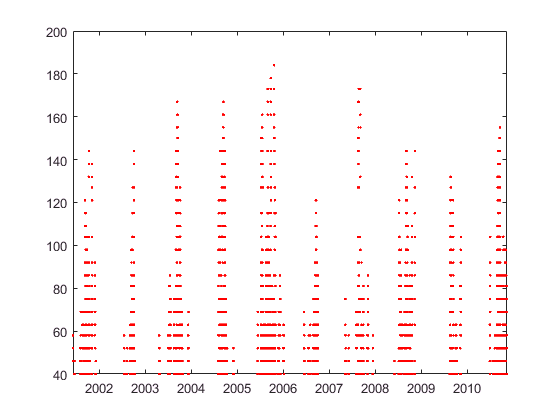


hold on
plot(winDate,Windspeed,'.r')
hold off

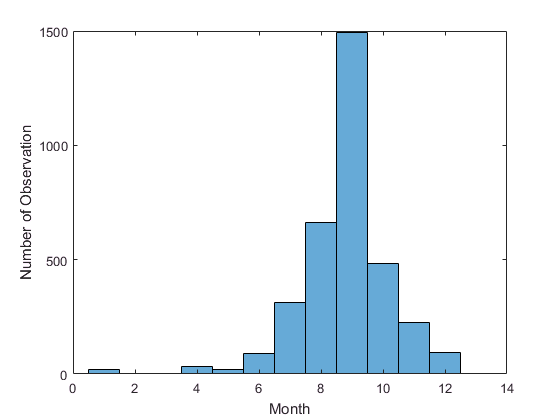


histogram(winMonth,'BinMethod','integer')
% custom binning
% histogram(winMonth,[1 6 7:14])
ylabel('Number of Observation');
xlabel('Month');